## Singular Value Decomposition

Consider $\vec{x}= \pmatrix{1 \cr 3} $ and $A = \pmatrix{2 & 1 \cr -1 & 1}$, then $\vec{y} = A\bar{x}=\pmatrix{2 & 1 \cr -1 & 1}\pmatrix{1 \cr 3} = \pmatrix{5\cr 2}$. $\overrightarrow{y}$ is basically a rotated and stretched form of $\overrightarrow{x}$. 

Now $\pmatrix{\cos{\theta} & -\sin{\theta} \cr \sin{\theta} & \cos{\theta} }$ is a rotation matrix and $\pmatrix{\alpha & 0 \cr 0 & \alpha}$, where $\alpha$ is a *positive real number*, is a stretching/translational matrix and $A$ is composed of these two.

Now consider a circle in 2-dimensions with its orthogonal direction co-ordinates being $v_1$ and $v_2$.

*(in n-dimensions it would be *$v_1 ,v_2 ,\;\ldotp \ldotp \ldotp \;,v_n$*)*

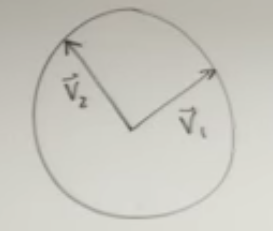

When an $A_{\mathrm{mxn}}$, is operated on this circle it becomes an ellipse (*it is rotated and then stretched*):

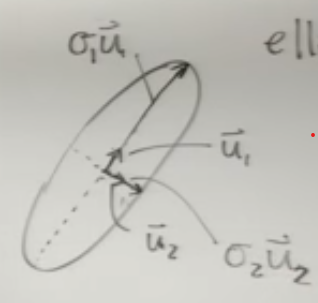

where $u_1$ and $u_2$ are the unit vectors in those directions and $\sigma_1$ and $\sigma_2$ are the distances along the unit vectos.

$\therefore $ $v_1 ,v_2 ,\;\ldotp \ldotp \ldotp \;,v_n$ vector space gets transformed to $u_1 ,u_2 ,\;\ldotp \ldotp \ldotp \;,u_n$ with $\sigma_1 ,\sigma_2 ,\;\ldotp \ldotp \ldotp \;,\sigma_n$ as stretching factors, when multiplied by $A$. The $\sigma_1 ,\sigma_2 ,\;\ldotp \ldotp \ldotp \;,\sigma_n$ are known as the ***singular values***.

Therefore in vector terms: $A\vec{v_j}=\sigma_j \vec{u_j}, \ j=1, 2, ..., n$.


$$\left[ \matrix{\cr A \cr \ } \right]_{mxn}
\left[\matrix{ \vec{v_1} & \vec{v_2} & ... & \vec{v_n} } \right]_{nxn} = 
\left[\matrix{ \vec{u_1} & \vec{u_2} & ... & \vec{u_n} } \right]_{mxn}
\left[\matrix{\sigma_1 &  &  & 0 \cr & \sigma_2 & & \cr  & & \ddots & \cr 0 & & & \sigma_n} \right]_{nxn}$$



$$\therefore
$$

$$\mathrm{AV}=\hat{U} \Sigma^ˆ$$


from $V$ and $\hat{U}$ it could be seen that these are unitary transformation matrices and orthogonal too. Thus $V^{-1} =V^*$and ${\hat{U} }^{-1} ={\hat{U} }^*$. On right multiplication with $V^{-1}$ we get

$A=\hat{U} \Sigma^ˆ V^*$ $\longrightarrow$ reduced SVD of A.

Since $\hat{U}$ is of size mxn, m-n extra silent columns can be added to make it mxm and the $\Sigma^ˆ$ can be stretched with m-n rows of 0's to make its size mxn.

$\therefore \  A_{mxn} = U_{mxm}\Sigma_{mxn} V^{*}_{nxn}$ $\longrightarrow$ **Singular Value Decomposition** of $\mathit{\mathbf{A}}$, where 

($\sigma_1 \ge \sigma_2 \ge \;\ldotp \ldotp \ldotp \;\ge \sigma_n \ge 0$).

To get the $U,\Sigma \;\mathrm{and}\;V$ matrices we follow these steps:


$$A^T A = (U \Sigma V^*)^T (U \Sigma V^*) \\
A^T A = V \Sigma  U^* U \Sigma V^* \\
A^T A = V \Sigma^2 V^*\\
A^T A V = (V \Sigma^2 V^*)V\\
\therefore A^T A V = \Sigma^2 V$$


This is the same as $\mathrm{Av}=\lambda v$, thus by solving this eigen-value problem we would get the $\Sigma^2$ and $V$ values.


$$A A^T = (U \Sigma V^*) (U \Sigma V^*)^T \\
A A^T = U \Sigma V^* V \Sigma U^* \\
A A^T = U \Sigma^2 U^* \\
A A^T U = (U \Sigma^2 U^*)U \\
\therefore A A^T U = \Sigma^2 U$$


clear all;close all;clc;
A = randi(10,3);
[u1, s1, v1] = svd(A);
[v2,ss21] = eig(A'*A);
[u2, ss12] = eig(A*A');
s2 = sqrt(ss12);
u1

u1 =    -0.6603   -0.0955   -0.7449
   -0.3666   -0.8247    0.4307
   -0.6555    0.5574    0.5095


u2

u2 =    -0.7449   -0.0955    0.6603
    0.4307   -0.8247    0.3666
    0.5095    0.5574    0.6555


disp("*****")

*****


s1

s1 =    18.8657         0         0
         0    9.2724         0
         0         0    3.0184


s2

s2 =     3.0184         0         0
         0    9.2724         0
         0         0   18.8657


disp("*****")

*****


v1

v1 =    -0.7015    0.2602   -0.6634
   -0.4391   -0.8911    0.1148
   -0.5613    0.3718    0.7394


v2

v2 =     0.6634    0.2602    0.7015
   -0.1148   -0.8911    0.4391
   -0.7394    0.3718    0.5613


$A^T A$ $\mathrm{and}$ ${\mathrm{AA}}^T$ are hermition matrices thus the eigen values are ***always*** *positive, real and distinct*.